clear
load("chips20.mat");
load("illum.mat");
load("xyz.mat");
load("Ad.mat");
load("Ad2.mat")
%Loading all necessary data

d=Ad'*(chips20(10,:).*CIEA)'

d =     0.0377
    0.0186
    0.0131


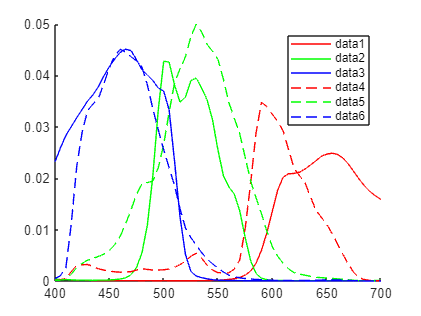

%1.1
colorRange=(400:5:700);
mycolors = [1 0 0; 0 1 0; 0 0 1];
ax=gca;
ax.ColorOrder=mycolors;
hold on
legend()
plot(colorRange,Ad)
plot(colorRange,Ad2,'--')
hold off

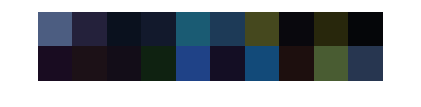

%1.2
dRaw=Ad'*(chips20.*CIED65)';
save("RGB_raw_D65","dRaw")
showRGB(dRaw')

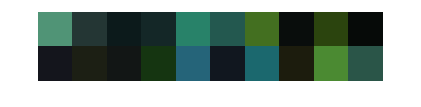

d=Ad2'*(chips20.*CIED65)';
showRGB(d')

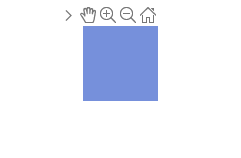

%2.1

%e=chips20.*CIED65; - Usual approach
e=ones(1,61);
d1=Ad'*(e)';
showRGB(d1')

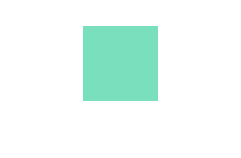

d2=Ad2'*(e)';
showRGB(d2')

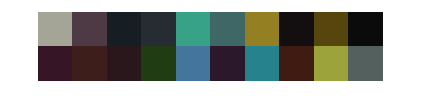

%2.2
load("RGB_raw_D65.mat")
RGB_cal_D65 = dRaw./d1;
save("RGB_cal_D65","RGB_cal_D65")
showRGB(RGB_cal_D65')

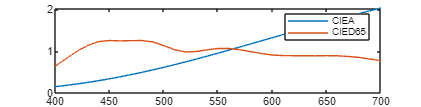

%2.3
plot(colorRange,CIEA)
hold on
plot(colorRange,CIED65)
legend("CIEA", "CIED65")

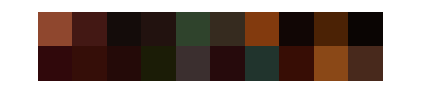

%2.4
d=Ad'*(chips20.*CIEA)';
showRGB(d')

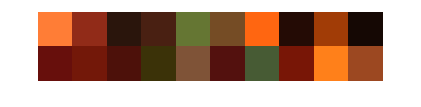

%Now calibrate
d=d./d1;
showRGB(d');

load("RGB_cal_D65.mat")
showRGB(RGB_cal_D65')

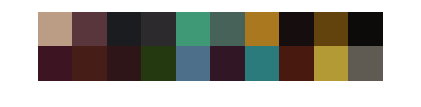

%2.5
%e=chips20.*CIED65; - Usual approach
%e=ones(1,61).*CIED65- Light specified
eD65=ones(1,61).*CIED65;
eA=ones(1,61).*CIEA;
d1=Ad'*(eD65)';
d2=Ad'*(eA)';
dCalD65=dRaw./d1;
dCalA=dRaw./d2;
showRGB(dCalD65')

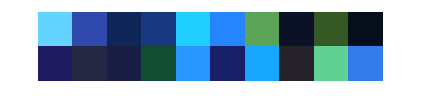

showRGB(dCalA')